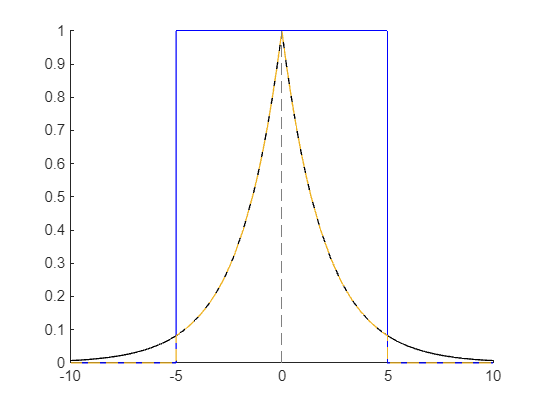

syms t real; f=exp(-abs(t)/2); 
L=10; w=rectangularPulse(-L/2, +L/2,t);

clf; figure; hold on; 
fplot(f,[-10,10],'Color','k'); fplot(w,[-10,10],'Color','b');
fplot(f*w,[-10 10],'LineStyle','--');
hold off;

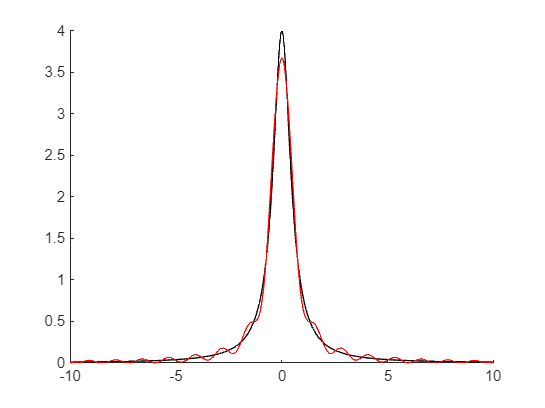


F=fourier(f,t); 
W=fourier(w,t);
G=fourier(f*w,t);

clf; figure; hold on;
fplot(abs(F),[-10,10], 'Color','k');
%fplot(abs(W),[-10,10], 'Color','b');
fplot(abs(G),[-10,10], 'Color','r');
hold off;

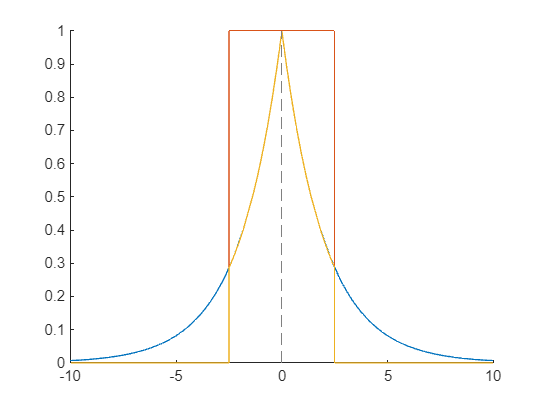



%--------------- L=5;
L2=5; w=rectangularPulse(-L2/2, +L2/2,t);

clf; figure; hold on; 
fplot(f,[-10,10]); fplot(w,[-10,10]);
fplot(f*w,[-10 10]);
hold off;

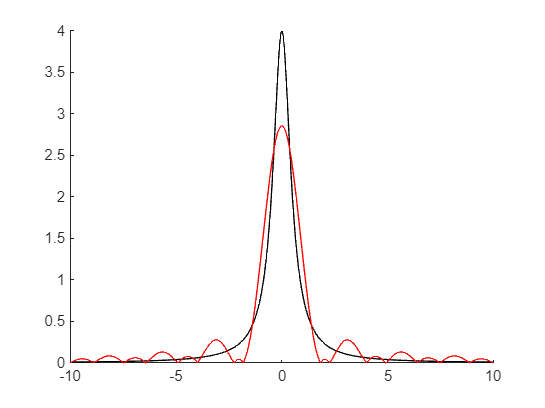


F=fourier(f,t); 
W=fourier(w,t);
G=fourier(f*w,t);

clf; figure; hold on;
fplot(abs(F),[-10,10], 'Color','k');
%fplot(abs(W),[-10,10], 'Color','b');
fplot(abs(G),[-10,10], 'Color','r');
hold off;

clf;

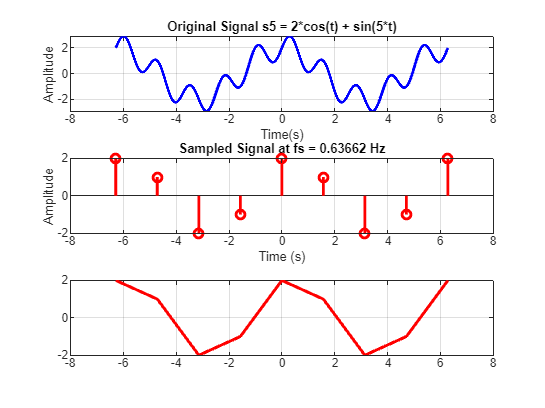

fs = 2/pi; %Sampling frequency of Sampling Step of s5

t_original = -2*pi:0.001:2*pi; %Taking an accurate number of samples
t_sampled = -2*pi:1/fs:2*pi; %Take 9 samples which don't satisfy the Sampling Theorem

% Define the original signal s5 = 2*cos(t) + sin(5*t)
s5 = 2*cos(t_original) + sin(5*t_original);

% Sample the signal s5 at the given sampling frequency fs
s5_sampled = 2*cos(t_sampled) + sin(5*t_sampled);

% Define s1 = 2*cos(t) + sin(t) for comparison
s1 = 2*cos(t_original) + sin(t_original);

clf; figure; subplot(3,1,1);
plot(t_original,s5,'b','LineWidth',2);
title('Original Signal s5 = 2*cos(t) + sin(5*t)');
xlabel('Time(s)'); ylabel('Amplitude'); grid on ;

subplot(3,1,2);
stem(t_sampled, s5_sampled, 'r', 'LineWidth', 2);
title(['Sampled Signal at fs = ' num2str(fs) ' Hz']);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
plot(t_sampled, s5_sampled,'r','LineWidth',2);
grid on;

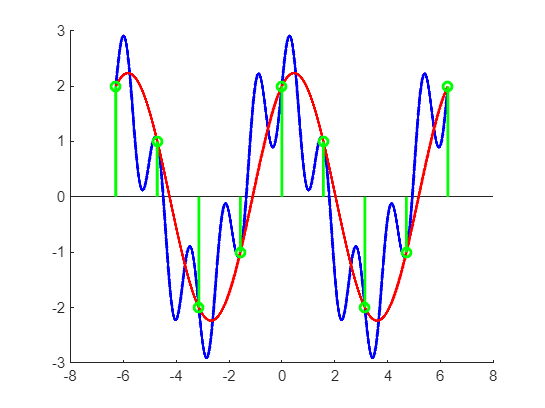


%-------

clf; figure; hold on;
plot(t_original,s5,'b','LineWidth',2);
plot(t_original,s1,'r','LineWidth',2);
stem(t_sampled, s5_sampled, 'og', 'LineWidth', 2);
hold off;

%We obtained points that can approximate well s1 but not s5

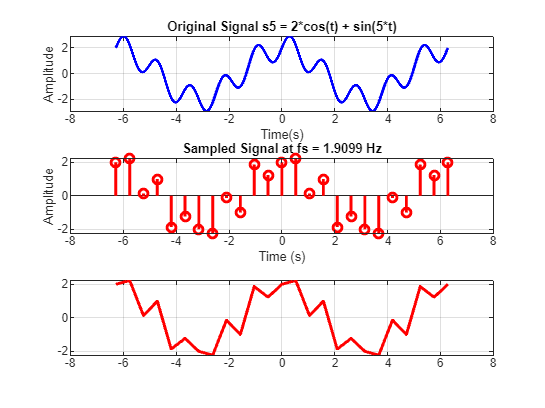

%Previous example but now we consider a frequency that satisfies the
%Sampling Theorem
fs=6/pi;
t_original = -2*pi:0.001:2*pi; %Taking an accurate number of samples
t_sampled = -2*pi:1/fs:2*pi;

% Define the original signal s5 = 2*cos(t) + sin(5*t)
s5 = 2*cos(t_original) + sin(5*t_original);

% Sample the signal s5 at the given sampling frequency fs
s5_sampled = 2*cos(t_sampled) + sin(5*t_sampled);

% Define s1 = 2*cos(t) + sin(t) for comparison
s1 = 2*cos(t_original) + sin(t_original);

clf; figure; subplot(3,1,1);
plot(t_original,s5,'b','LineWidth',2);
title('Original Signal s5 = 2*cos(t) + sin(5*t)');
xlabel('Time(s)'); ylabel('Amplitude'); grid on ;

subplot(3,1,2);
stem(t_sampled, s5_sampled, 'r', 'LineWidth', 2);
title(['Sampled Signal at fs = ' num2str(fs) ' Hz']);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
plot(t_sampled, s5_sampled,'r','LineWidth',2);
grid on;

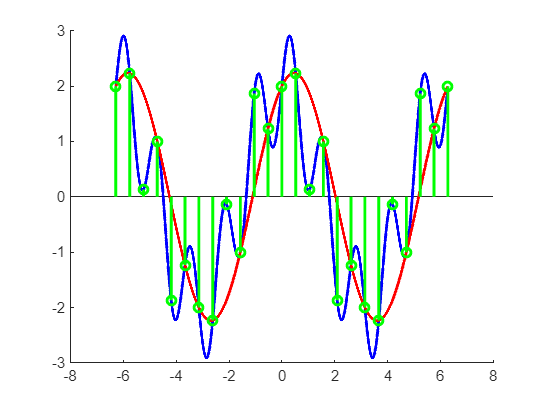


%-------

clf; figure; hold on;
plot(t_original,s5,'b','LineWidth',2);
plot(t_original,s1,'r','LineWidth',2);
stem(t_sampled, s5_sampled, 'og', 'LineWidth', 2);
hold off;

%In this plot we see as not every green circle is a point of s1.
%In this case there is no aliasing effect

fs=1000; %Sampling frequency
T=1/fs; %Sampling period;
L=2*pi; % Lenght of the Signal
t=-2*pi:T:2*pi;
signal = @(x) cos(x)+sin(10*x);
t_vals = signal(t)

t_vals =     1.0000    1.0100    1.0200    1.0300    1.0400    1.0500    1.0599    1.0699    1.0799    1.0898    1.0998    1.1097    1.1196    1.1295    1.1394    1.1493    1.1592    1.1690    1.1789    1.1887    1.1985    1.2082    1.2180    1.2277    1.2374    1.2471    1.2567    1.2664    1.2760    1.2855    1.2951    1.3046    1.3141    1.3235    1.3329    1.3423    1.3516    1.3609    1.3702    1.3794    1.3886    1.3978    1.4069    1.4159    1.4250    1.4340    1.4429    1.4518    1.4606    1.4694


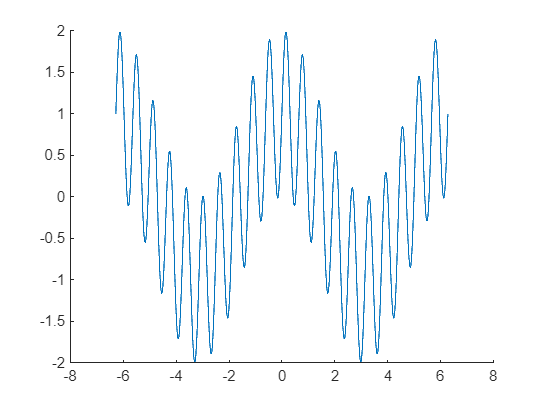


FT = fft(t_vals);

clf; figure; hold on;
plot(t,t_vals);
hold off;


clf; figure; hold on;
plot(t,FT);

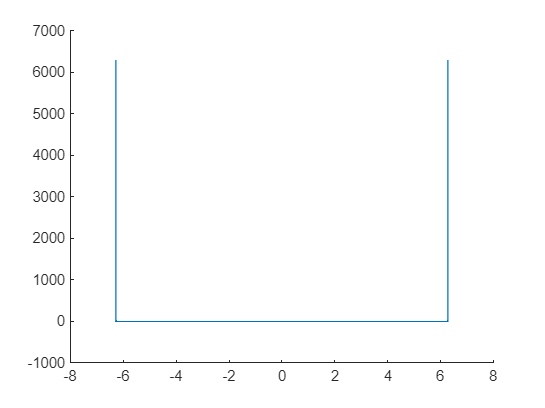

hold off;

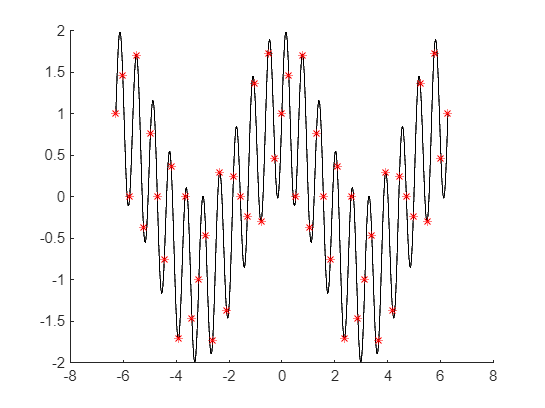


fs=12/pi;
t_sampled = -2*pi:1/fs:2*pi;
t_sampled_vals = signal(t_sampled);

FT=fft(t_sampled_vals);

clf; figure; hold on;
plot(t,t_vals,'Color','black');
plot(t_sampled,t_sampled_vals,'*r');
hold off;

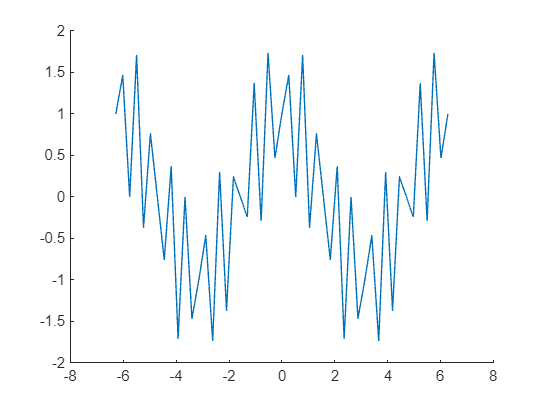


clf; figure; hold on;
plot(t_sampled,real(ifft(FT)));
hold off;

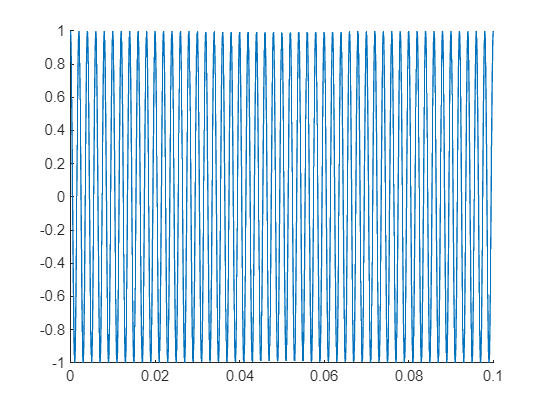

L=1000;
t=linspace(0,0.1,L);
f= @(x) cos(x*pi*1000);
t_vals = f(t);


clf; figure; hold on;
plot(t,t_vals);
hold off;

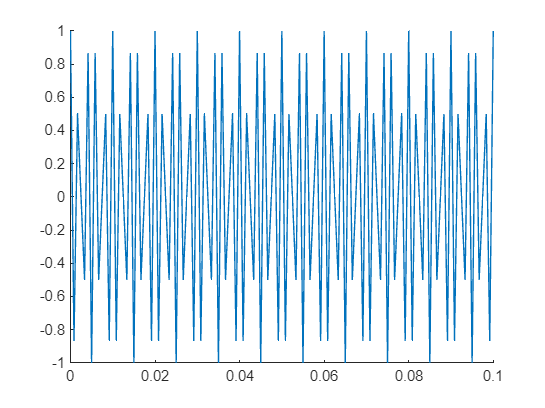


fs=1200;
t=linspace(0,0.1,L);
t=0:1/fs:0.1;
f= @(x) cos(x*pi*1000);
t_vals = f(t);

clf; figure; hold on;
plot(t,t_vals);
hold off;